# Tutorial 4: Running Forward Kinematics in CASPR

Forward kinematics for cable-driven robots (CDRs) refer to the determination of the robot pose for a given set of cable lengths. 

This tutorial shows how to run inverse kinematics through two approaches:

- ForwardKinematicsSimulator

- Writing your own time loop

## Setup (required for both approaches)

### Load the robot and trajectory

Load a robot as shown in `T1_load_robot.mlx `and` T2_load_trajectory.mlx`

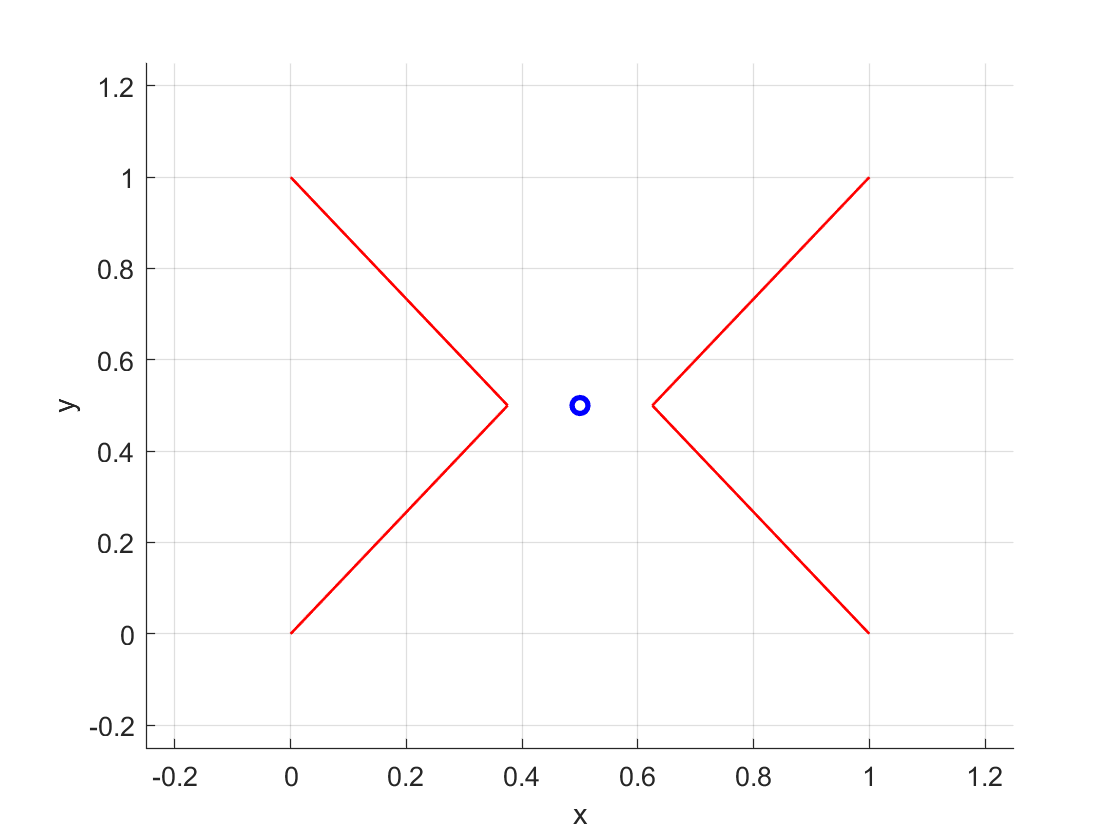

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Run inverse kinematics for input to the forward kinematics

In practice, the cable lengths may be obtained from the robot hardware. However, this simulation example, the inverse kinematics cable lengths solution will be used as input to the forward kinematics. 

The steps are the same as that from `tutorial_IK.mlx`

ik_sim = InverseKinematicsSimulator(cdpr_model);
ik_sim.run(trajectory);

[INFO] Begin inverse kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] T

Original joint pose (to be solved using FK):

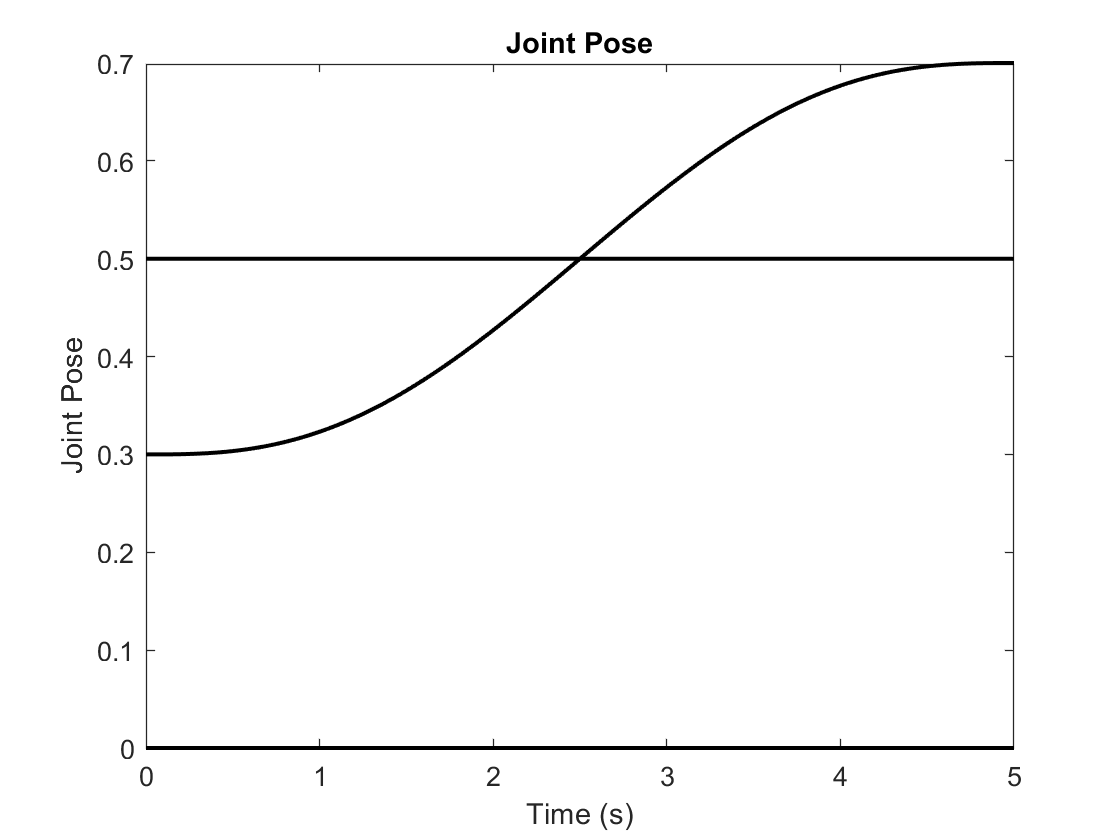

ik_sim.plotJointPose();

### Setup forward kinematics solver

Since there are many potential ways to solve for the forward kinematics, CASPR offer different solvers that can be used for the simulator. For example, using the least squares method

fk_solver = FKLeastSquares(cdpr_model, FK_LS_ApproxOptionType.FIRST_ORDER_INTEGRATE_PSEUDOINV, FK_LS_QdotOptionType.FIRST_ORDER_DERIV); % Refer to FKLeastSquares.m for more details

Setup some initial values for use later:

init_q = ik_sim.trajectory.q{1}; % Initial q for the solver
init_q_dot = ik_sim.trajectory.q_dot{1}; % Initial q_dot for the solver

## 1) Solve using the ForwardKinematicsSimulator

The Forward`KinematicsSimulator` provides the simplest way to run a "standard" forward kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model and the specified solver:

fk_sim = ForwardKinematicsSimulator(cdpr_model, fk_solver);

Next, run the simulator on the resulting cable lengths and cable lengths velocity over the specified time points with the initial joint pose and velocity:

fk_sim.run(ik_sim.cableLengths, ik_sim.cableLengthsDot, ik_sim.timeVector, init_q, init_q_dot);

[INFO] Begin forward kinematics simulator run...
[INFO] Time : 0.000000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 1
[INFO] Time : 0.050000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[INFO] Time : 0.100000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[INFO] Time : 0.150000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[INFO] Time : 0.200000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[INFO] Time : 0.250000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[INFO] Time : 0.300000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000001. Number of function calls: 4
[INFO] Time : 0.350000
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000002. Number of function calls: 4
[INFO] Time : 0.400000
[DEBUG] Function

The forward kinematics simulator can plot the joint pose, but also resulting cable length error resulting from the joint pose results

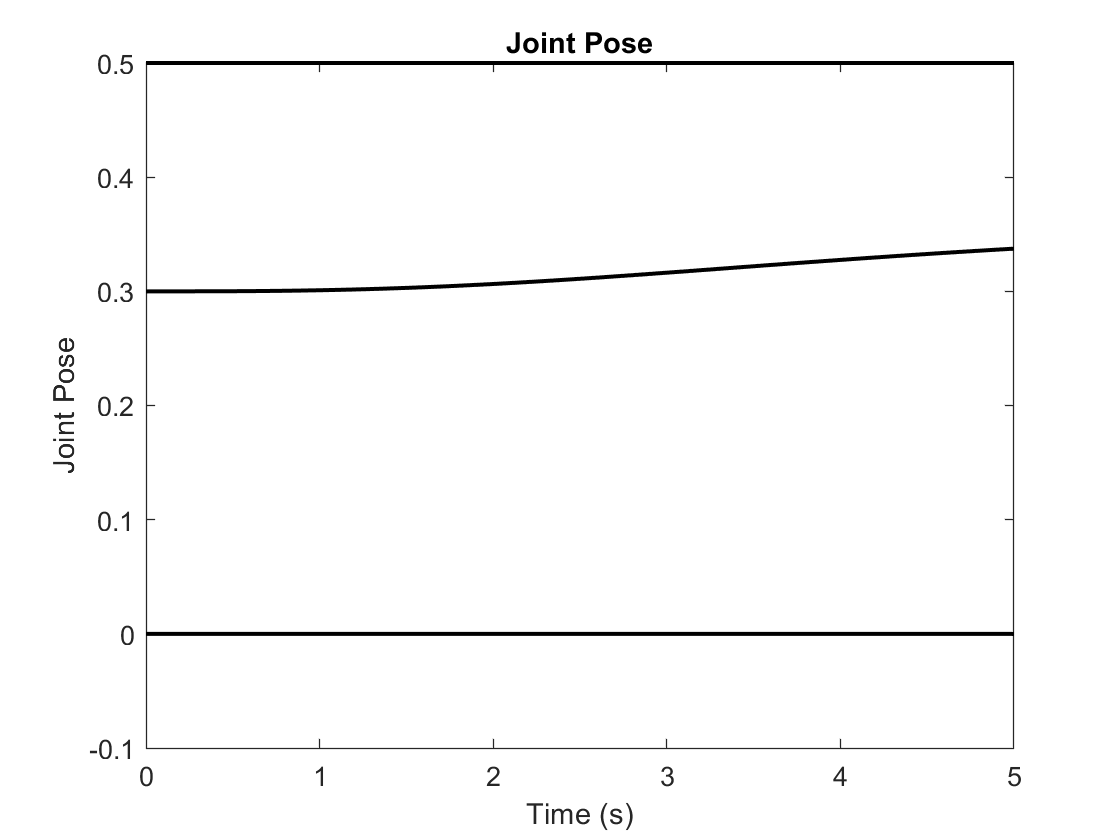

fk_sim.plotJointPose();

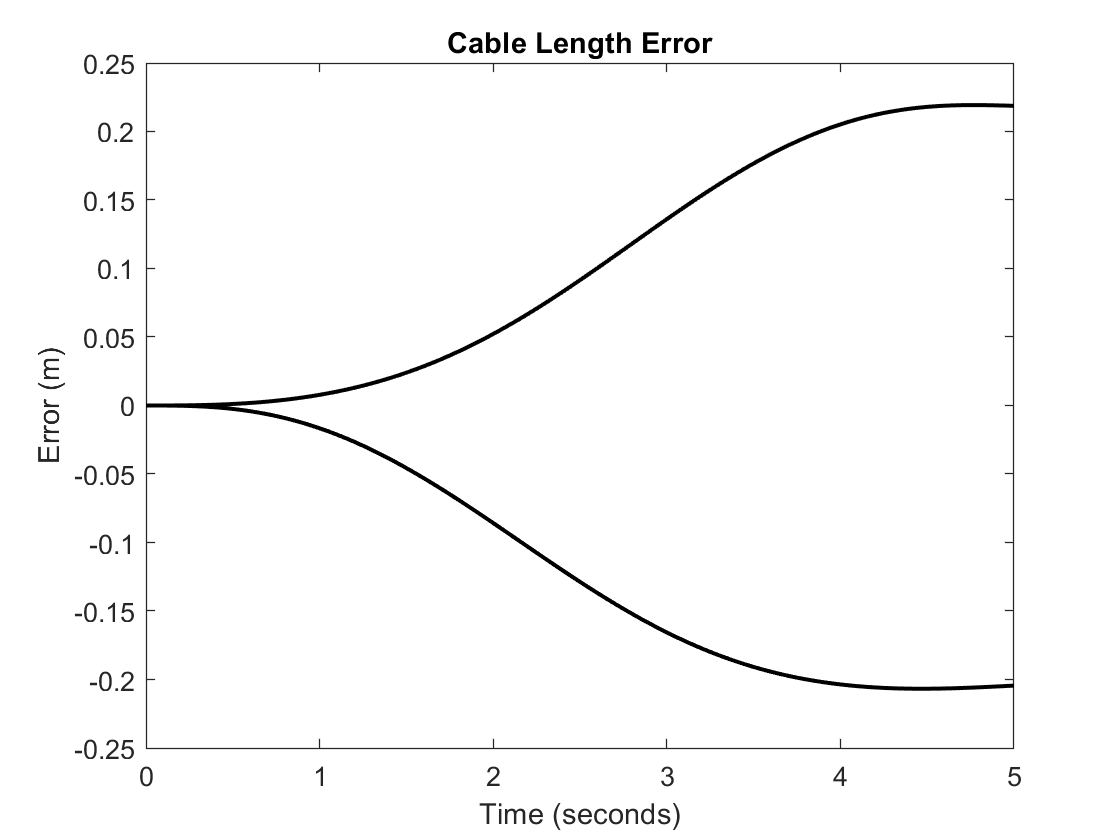

fk_sim.plotCableLengthError();

The simulator also stores some useful information:

fprintf('Total time: %f seconds\n', fk_sim.compTimeTotal);

Total time: 6.012046 seconds


fprintf('Total length error: %f\n', fk_sim.lengthErrorTotal);

Total length error: 22.059590


## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the Forward`KinematicsSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

fk_solution = zeros(cdpr_model.numDofs, length(trajectory.timeVector)); % Each column is the solution at each time step
comp_time = zeros(length(trajectory.timeVector), 1);

Setup some initial variables, previous length, previous joint pose and previous joint velocity. This is required by the forward kinematics solvers.

len_prev = ik_sim.cableLengths{1};          % Initialise the previous length as the first set of cable lengths
q_prev_leastsquares = init_q;               
q_dot_prev_leastsquares = init_q_dot;       

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory.timeVector)

[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 1
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000000. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000001. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000002. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000004. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000009. Number of function calls: 3
[DEBUG] Function lsqnonlin completed. Fitting error: 0.000016. Number of function calls: 3

The main step within the time loop is to call the solver to resolve the forward kinematics:

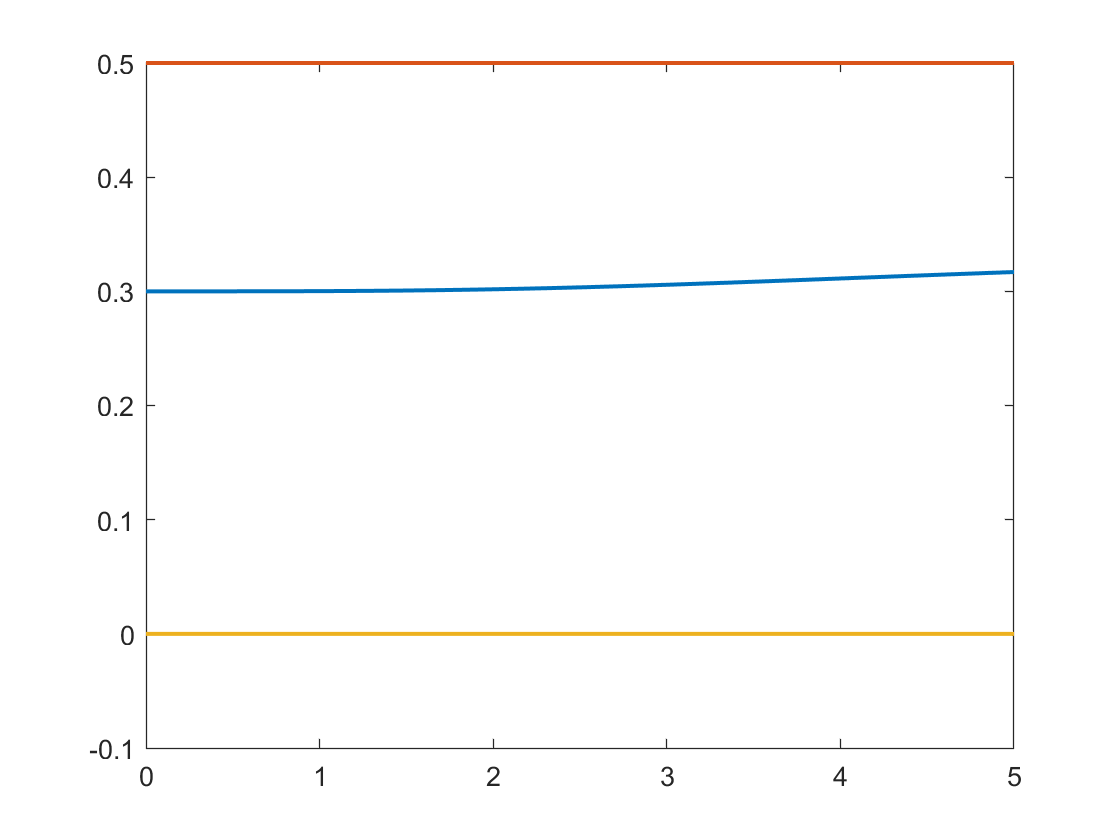

    % Compute for the least squares method forward kinematics solver
    [q_sol, q_dot_sol, comp_time(t)] = fk_solver.compute(ik_sim.cableLengths{t}, len_prev, q_prev_leastsquares, q_dot_prev_leastsquares, trajectory.timeStep);
    fk_solution(:, t) = q_sol;

    q_prev_leastsquares = q_sol;
    q_dot_prev_leastsquares = q_dot_sol;

Total time: 3.869684 seconds


    
    % Store cable length for next loop
    len_prev = ik_sim.cableLengths{t};
end

The results can be plotted the way you desire yourself.

figure; 

[INFO] Begin forward kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] T

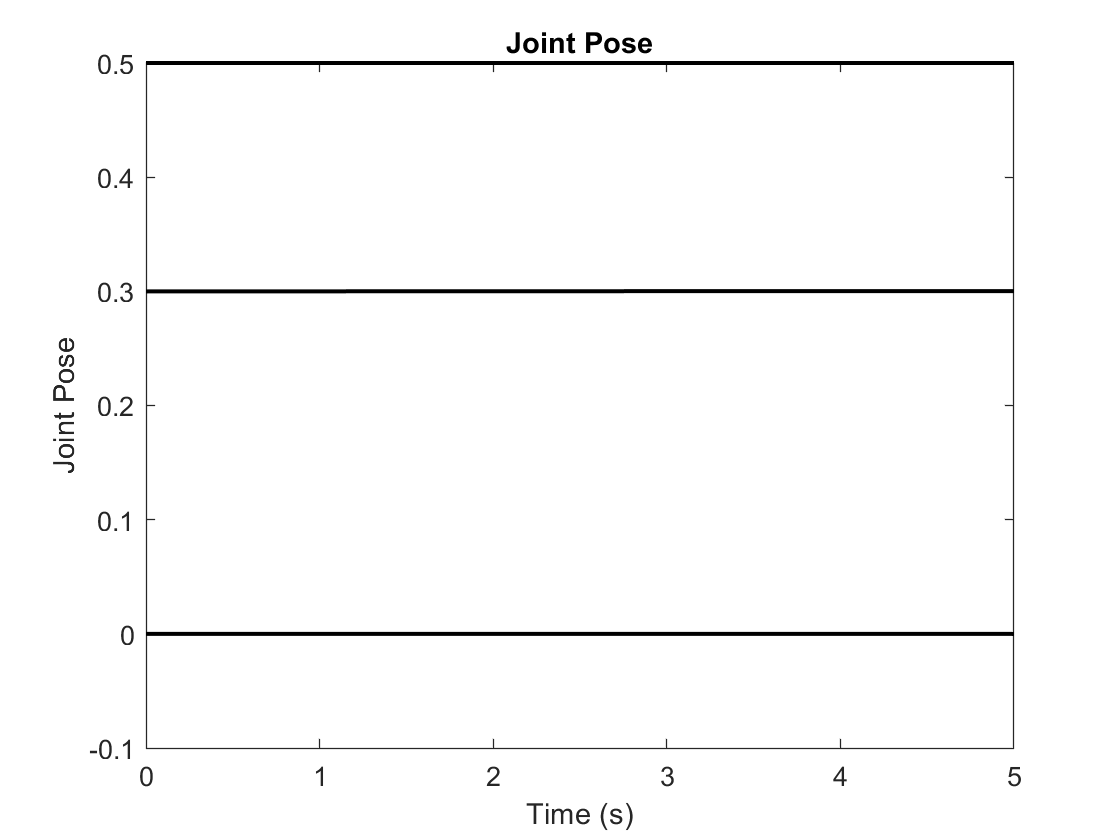

plot(trajectory.timeVector, fk_solution, 'LineWidth', 1.5);


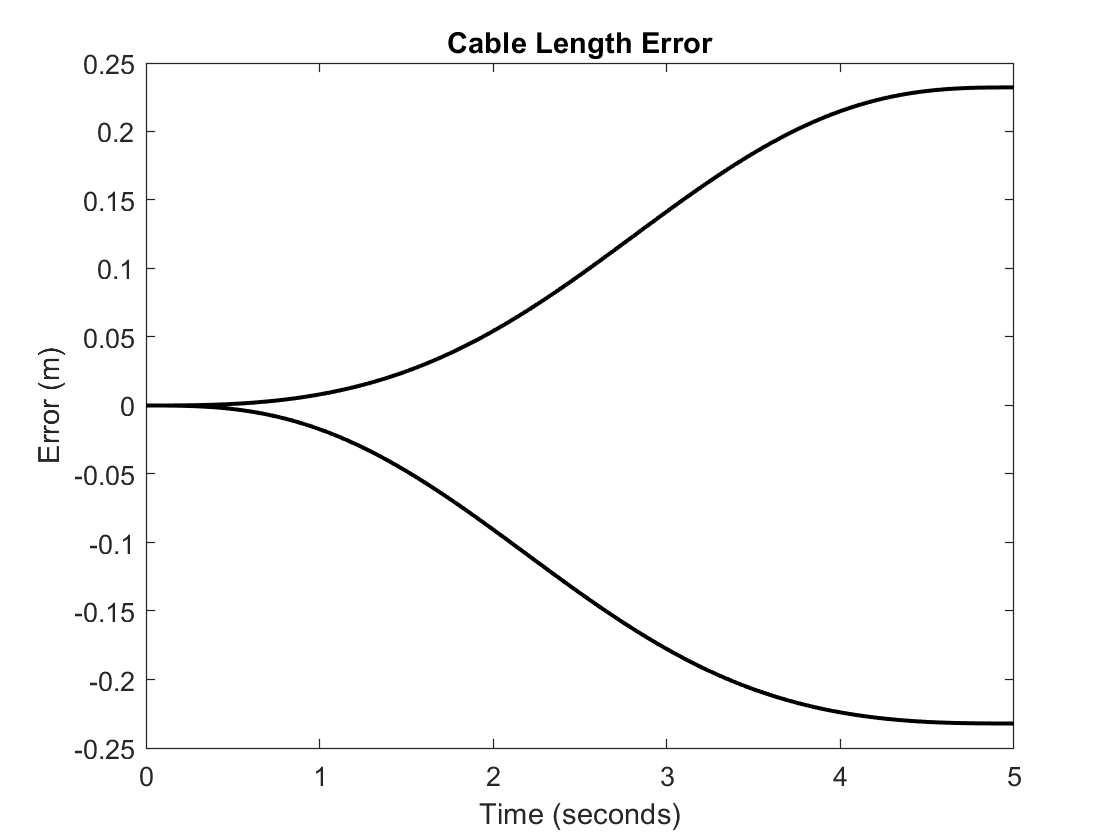

fprintf('Total time: %f seconds\n', sum(comp_time));

## Running another forward kinematics solver

Another forward kinematics solver, `FKDifferential`, will be shown to compare with the `FKLeastSquares` solver. Refer to `~/src/Analysis/ForwardKinematics/` folder for more solvers that you can use.

fk_diff_solver = FKDifferential(cdpr_model); % Refer to ~/src/Analysis/ForwardKinematics/DifferentialMethod/FKDifferential.m for more details

For least squares method:


fk_sim_diff = ForwardKinematicsSimulator(cdpr_model, fk_diff_solver);

Total time: 6.012046 seconds


fk_sim_diff.run(ik_sim.cableLengths, ik_sim.cableLengthsDot, ik_sim.timeVector, init_q, init_q_dot);

Total length error: 22.059590


Again, the performance of the solver can be observed by plotting the resulting joint poses and the cable length error:

fk_sim_diff.plotJointPose();

For differential method:


fk_sim_diff.plotCableLengthError();

Total time: 0.191308 seconds


It can be seen that the least squares method is more accurate (lower error) but is more time consuming compared with the differential method. 

% Print information related to the least squares method simulation

Total length error: 23.609543


fprintf('For least squares method:\n'); 
fprintf('Total time: %f seconds\n', fk_sim.compTimeTotal);
fprintf('Total length error: %f\n', fk_sim.lengthErrorTotal);
% Print information related to the differential method simulation
fprintf('For differential method:\n');
fprintf('Total time: %f seconds\n', fk_sim_diff.compTimeTotal);
fprintf('Total length error: %f\n', fk_sim_diff.lengthErrorTotal);
